# Só para o Sid usar (melhor código aqui meus putos)

Aqui é Naive Bayes

% Ler o ficheiro CSV
data = readtable('dataset.csv');
% Exibir os nomes das colunas
%disp(data.Properties.VariableNames);

% Dividir a coluna única em duas: Frases e Categoria
splitData = split(data.Text, ' : ');

frases = splitData(:, 1); % Coluna com as frases
%categorias = splitData(:, 2); % Coluna com as categoria


categorias = cell(height(data), 1);
for ctg = 1 : height(data)
    categorias{ctg} = data.Category{ctg};
end
%disp(categorias);

%rrmover linhas duplicadas
%(fazer isto)


% ------------------------------
%dividir o dataset em treino e teste (60% treino, 40% teste)

% Total de linhas
numRows = size(data, 1);

% Gerar índices aleatórios
randIndices = randperm(numRows);

% Determinar limites para treino e teste
trainLimit = round(0.6 * numRows);

% Conjuntos de treino e teste
trainIndices = randIndices(1:trainLimit);
testIndices = randIndices(trainLimit + 1:end);

% Separar frases e categorias para treino
trainFrases = frases(trainIndices);
trainCategorias = categorias(trainIndices);

% Separar frases e categorias para teste
testFrases = frases(testIndices);
testCategorias = categorias(testIndices);

% Exibir resultados para validação
%disp('Conjunto de treino (frases):');
%disp(trainFrases);

%disp('Conjunto de treino (categorias):');
%disp(trainCategorias);

%disp('Conjunto de teste (frases):');
%disp(testFrases);

%disp('Conjunto de teste (categorias):');
%disp(testCategorias);
    
%--------------------------------

% Processamento das trainFrases

% Converter as frases para string para facilitar o processamento
trainFrases = string(trainFrases);
trainFrases = lower(trainFrases);
frasestoken = tokenizedDocument(trainFrases);
%customStopWords = [stopWords "there's" "someone"];
%customStopWords = string(customStopWords);

% Remover as stopwords usando removeStopWords
cleanfrasestoken = removeStopWords(frasestoken);
cleanfrases = joinWords(cleanfrasestoken);

trainFrases = string(cleanfrases);
%remover pontos finais das frases
trainFrases = regexprep(trainFrases, '\.$', '');
%remover virgulas das frases
trainFrases = regexprep(trainFrases, ',', '');


%converter texto em minusculas
trainFrases = lower(trainFrases);
disp(trainFrases);

    "there's dangerous gas leak "
    "stuck elevator "
    "there's chemical spill factory "
    "there's medical emergency "
    "someone tampering fire hydrant "
    "there's person stuck tree parachute malfunction "
    "there's person hypothermia "
    "need assistance stuck elevator "
    "there's dangerous gas leak "
    "there's smoke filling hallway "
    "there's person stranded island "
    "need report child neglect "
    "need emergency assistance "
    "need report reckless driver "
    "building construction collapsed "
    "there's emergency amusement park "
    "think person stuck radio tower "
    "think there's carbon monoxide leak "
    "heard screams coming alley "
    "smoke coming engine compartment "
    "need medical assistance "
    "there's person injured construction accident "
    "loud explosion "
    "need help  spouse choking "
    "someone distress bridge "
    "there's person experiencing severe dehydration "
    "there's crane toppled "
    "there's e



% Processamento das testFrases

% Converter as frases para string para facilitar o processamento
testFrases = string(testFrases);
testFrases = lower(testFrases);
frasestoken = tokenizedDocument(testFrases);
%customStopWords = [stopWords "there's" "someone"];
%customStopWords = string(customStopWords);

% Remover as stopwords usando removeStopWords
cleanfrasestoken = removeStopWords(frasestoken);
cleanfrases = joinWords(cleanfrasestoken);

testFrases = string(cleanfrases);
%remover pontos finais das frases
testFrases = regexprep(testFrases, '\.$', '');
%remover virgulas das frases
testFrases = regexprep(testFrases, ',', '');


%converter texto em minusculas
testFrases = lower(testFrases);
disp(testFrases);

    "neighbor's roof collapsed "
    "someone trapped collapsed mine "
    "smell smoke find source "
    "hear gunshots neighborhood "
    "someone trapped burning building "
    "person fell height injured "
    "someone experiencing hypothermia symptoms "
    "someone trapped vehicle collision "
    "someone experiencing severe back pain "
    "there's person experiencing severe dizziness "
    "heard explosion underground "
    "someone fell open manhole "
    "there's crowd gathering things getting heated "
    "someone bitten venomous snake "
    "there's vehicle blocking emergency access "
    "someone unconscious electrocuted "
    "there's gas leak apartment complex "
    "there's person lying unconscious park "
    "someone unresponsive bee sting "
    "need report medical emergency concert "
    "heard window break downstairs "
    "there's suspicious vehicle parked outside "
    "witnessed chemical spill highway "
    "someone trapped vehicle "
    "boat sinking "
    "ther


%------------------------------

%criar o vocabulário único das frases (lista de palavras únicas)
vocabulary = createVocabulary(trainFrases);
%remover strings vazias
vocabulary = vocabulary(vocabulary ~= "")

vocabulary = 296×1 string array
    "accident"
    "accidents"
    "acting"
    "active"
    "affecting"
    "aggressive"
    "air"
    "airplane"
    "airport"
    "alarm"
    "alert"
    "allergic"
    "alley"
    "ambulance"
    "amusement"
    "animal"
    "approaching"
    "area"
    "assaulted"
    "assistance"
    "attack"
    "badly"
    "bang"
    "basement"
    "bee"
    "beeping"
    "bleeding"
    "blocked"
    "blocking"
    "boating"


%disp('Vocabulário único:');
%disp(vocabulary);

%------------------------------

%criar a matriz Bag-of-Words (número de ocorrências)
numFrases = length(trainFrases);
numWords = length(vocabulary);

%inicializar a matriz com zeros
matriz_ocorrencias = zeros(numFrases, numWords);

%preencher a matriz Bag-of-Words
for ctg = 1:numFrases
    %dividir a frase atual em palavras
    words = split(trainFrases{ctg});
    for j = 1:numWords
        %contar as ocorrências da palavra atual na frase atual
        matriz_ocorrencias(ctg, j) = sum(strcmp(words, vocabulary{j}));
    end
end

%exibir a matriz de ocorrências - linhas = frases || colunas = palavras
%ou seja, esta é a primeira linha da matriz
%1     0     0     0     0     0
%significa que na primeria frase aparece uma vez a primeria palavra da Bag-of-Words
disp('Matriz Ocorrências:');

Matriz Ocorrências:


disp(matriz_ocorrencias);

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

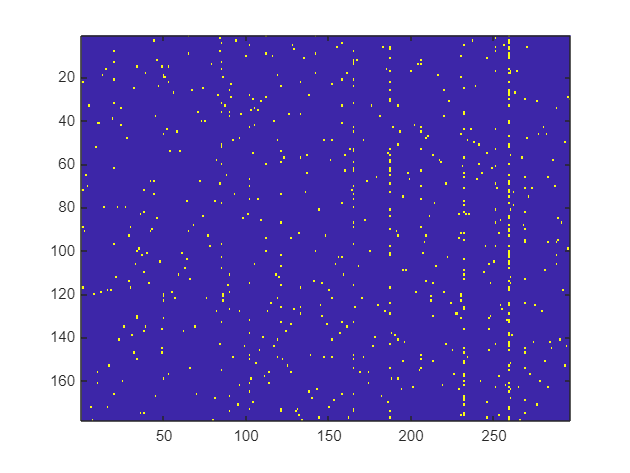

imagesc(matriz_ocorrencias)


% ------------------------------

% Criar um vetor com a frase correspondente a cada linha da matriz
% O vetor será simplesmente as frases, já que cada linha da matriz ocorrências
% corresponde a uma frase única.
fraseCorrespondente = trainFrases;
disp(trainFrases);

    "there's dangerous gas leak "
    "stuck elevator "
    "there's chemical spill factory "
    "there's medical emergency "
    "someone tampering fire hydrant "
    "there's person stuck tree parachute malfunction "
    "there's person hypothermia "
    "need assistance stuck elevator "
    "there's dangerous gas leak "
    "there's smoke filling hallway "
    "there's person stranded island "
    "need report child neglect "
    "need emergency assistance "
    "need report reckless driver "
    "building construction collapsed "
    "there's emergency amusement park "
    "think person stuck radio tower "
    "think there's carbon monoxide leak "
    "heard screams coming alley "
    "smoke coming engine compartment "
    "need medical assistance "
    "there's person injured construction accident "
    "loud explosion "
    "need help  spouse choking "
    "someone distress bridge "
    "there's person experiencing severe dehydration "
    "there's crane toppled "
    "there's e


% ------------------------------

% numero de casos favoraveis/ numero de casos possiveis 
% P(I) - prob de calhar I a dividir por todos
% P(B) - ...
% P(P) - ...

% Depois tenho que fazer a % P("palavra_à_escolha"|I) = (categoria palavra_à_escolha na classe I) / (numero de palavras na classe I)
% fazer isto para os três casos, I, P, B


%calcular P(I), P(B) e P(P)

%categorias
categorias_unicas = ['I', 'B', 'P'];

%probs das categorias
probabilidades_categoria = zeros(length(categorias_unicas), 1);

%contar ocorrências de cada categoria e calcular a probabilidade
for ctg = 1:length(categorias_unicas)
    categoria_count = sum(strcmp(trainCategorias, categorias_unicas(ctg))); %retorna 1 se forem iguais e soma todos os 1
    probabilidades_categoria(ctg) = categoria_count / length(trainCategorias); %casos favoraveis a dividir por casos totais
end


%exibir as probabilidades das categorias
disp('Probabilidades das categorias:');

Probabilidades das categorias:


for ctg = 1:length(categorias_unicas)
    fprintf('P(%s) = %.3f\n', categorias_unicas(ctg), probabilidades_categoria(ctg));
end

P(I) = 0.270
P(B) = 0.539
P(P) = 0.191


%calcular probs condicionadas

%criar matriz prob cond para cada palavra dada uma categoria
num_categorias = length(categorias_unicas);
prob_cond = zeros(num_categorias, numWords); %aqui linhas = categorias e colunas = palavras

%suavização de laplace (para evitar prob zero)
suavizacao_laplace = 1;

%calcular P(palavra | categoria)
for c = 1:num_categorias
    %vou filtrar frases que pertencem à categoria atual
    categoria_atual = categorias_unicas(c);
    indices_categorias = strcmp(trainCategorias, categoria_atual); %retorna 1 se for a mesma categoria
    frases_categoria = trainFrases(indices_categorias);

    %contar ocorrências de cada palavra nas frases da categoria
    total_palavras_categoria = 0;
    palavras_por_categoria = zeros(1, numWords); %counter para cada palavra

    for f = 1:length(frases_categoria)
        %dividir frase em palavras
        palavras = split(frases_categoria{f});

        %atualizar contadores
        total_palavras_categoria = total_palavras_categoria + length(palavras);

        for p = 1:numWords
            palavras_por_categoria(p) = palavras_por_categoria(p) + sum(strcmp(palavras, vocabulary{p}));
        end
    end

    %calcular probs cond
    prob_cond(c, :) = (palavras_por_categoria + suavizacao_laplace) ./ (total_palavras_categoria + numWords * suavizacao_laplace);
end


for ctg = 1:num_categorias
    fprintf('Probabilidades condicionais para a categoria %s:\n', categorias_unicas(ctg));
    for j = 1:numWords
        fprintf('P(%s | %s) = %.4f\n', vocabulary{j}, categorias_unicas(ctg), prob_cond(ctg, j));
    end
    fprintf('\n');
end

Probabilidades condicionais para a categoria I:


P(accident | I) = 0.0075
P(accidents | I) = 0.0019
P(acting | I) = 0.0019
P(active | I) = 0.0019
P(affecting | I) = 0.0038
P(aggressive | I) = 0.0019
P(air | I) = 0.0019
P(airplane | I) = 0.0019
P(airport | I) = 0.0038
P(alarm | I) = 0.0038
P(alert | I) = 0.0038
P(allergic | I) = 0.0038
P(alley | I) = 0.0019
P(ambulance | I) = 0.0019
P(amusement | I) = 0.0038
P(animal | I) = 0.0019
P(approaching | I) = 0.0019
P(area | I) = 0.0019
P(assaulted | I) = 0.0019
P(assistance | I) = 0.0132
P(attack | I) = 0.0038
P(badly | I) = 0.0019
P(bang | I) = 0.0019
P(basement | I) = 0.0019
P(bee | I) = 0.0038
P(beeping | I) = 0.0019
P(bleeding | I) = 0.0019
P(blocked | I) = 0.0019
P(blocking | I) = 0.0019
P(boating | I) = 0.0038
P(bomb | I) = 0.0019
P(bridge | I) = 0.0038
P(broken | I) = 0.0019
P(building | I) = 0.0019
P(burglary | I) = 0.0019
P(burning | I) = 0.0019
P(calling | I) = 0.0019
P(car | I) = 0.0057
P(carbon | I) = 0.0019
P(caught | I) = 0.0019
P(cause | I) = 0.0019
P(causing | I) = 0.0019
P(c

Probabilidades condicionais para a categoria B:


P(accident | B) = 0.0013
P(accidents | B) = 0.0013
P(acting | B) = 0.0013
P(active | B) = 0.0025
P(affecting | B) = 0.0013
P(aggressive | B) = 0.0025
P(air | B) = 0.0013
P(airplane | B) = 0.0025
P(airport | B) = 0.0013
P(alarm | B) = 0.0038
P(alert | B) = 0.0013
P(allergic | B) = 0.0013
P(alley | B) = 0.0013
P(ambulance | B) = 0.0025
P(amusement | B) = 0.0013
P(animal | B) = 0.0038
P(approaching | B) = 0.0025
P(area | B) = 0.0025
P(assaulted | B) = 0.0013
P(assistance | B) = 0.0025
P(attack | B) = 0.0013
P(badly | B) = 0.0025
P(bang | B) = 0.0025
P(basement | B) = 0.0038
P(bee | B) = 0.0013
P(beeping | B) = 0.0025
P(bleeding | B) = 0.0025
P(blocked | B) = 0.0025
P(blocking | B) = 0.0038
P(boating | B) = 0.0013
P(bomb | B) = 0.0013
P(bridge | B) = 0.0025
P(broken | B) = 0.0025
P(building | B) = 0.0076
P(burglary | B) = 0.0013
P(burning | B) = 0.0038
P(calling | B) = 0.0025
P(car | B) = 0.0038
P(carbon | B) = 0.0038
P(caught | B) = 0.0025
P(cause | B) = 0.0025
P(causing | B) = 0.0025
P(c

Probabilidades condicionais para a categoria P:


P(accident | P) = 0.0044
P(accidents | P) = 0.0044
P(acting | P) = 0.0044
P(active | P) = 0.0022
P(affecting | P) = 0.0022
P(aggressive | P) = 0.0022
P(air | P) = 0.0044
P(airplane | P) = 0.0022
P(airport | P) = 0.0022
P(alarm | P) = 0.0022
P(alert | P) = 0.0022
P(allergic | P) = 0.0022
P(alley | P) = 0.0044
P(ambulance | P) = 0.0022
P(amusement | P) = 0.0022
P(animal | P) = 0.0022
P(approaching | P) = 0.0022
P(area | P) = 0.0022
P(assaulted | P) = 0.0044
P(assistance | P) = 0.0022
P(attack | P) = 0.0022
P(badly | P) = 0.0022
P(bang | P) = 0.0022
P(basement | P) = 0.0022
P(bee | P) = 0.0022
P(beeping | P) = 0.0022
P(bleeding | P) = 0.0022
P(blocked | P) = 0.0022
P(blocking | P) = 0.0022
P(boating | P) = 0.0044
P(bomb | P) = 0.0044
P(bridge | P) = 0.0022
P(broken | P) = 0.0022
P(building | P) = 0.0022
P(burglary | P) = 0.0044
P(burning | P) = 0.0022
P(calling | P) = 0.0022
P(car | P) = 0.0044
P(carbon | P) = 0.0022
P(caught | P) = 0.0022
P(cause | P) = 0.0022
P(causing | P) = 0.0044
P(c



%--------------------

% depois para finalizar naive bayes:
% P(categoria∣frase) = P(categoria) * ∏ P(palavra∣categoria) , ∏ é o multiplicatório
% é melhor usamos logaritmo para evitar underflow, valores muito pequenos


% inicializar vetor para armazenar categorias previstas
categorias_previstas = strings(length(testFrases), 1);

% variavel para avaliar precisão (ver quantas estão corretas)
correto = 0;

% Classificar cada frase de teste
for i = 1:length(testFrases)
    % Dividir a frase de teste em palavras
    words = split(testFrases{i});
    
    % Inicializar vetor para probabilidades posteriores
    prob_posterior = zeros(num_categorias, 1);
    
    % Calcular a probabilidade posterior para cada categoria
    for c = 1:num_categorias
        % P(Categoria) inicial (log)
        prob_posterior(c) = log(probabilidades_categoria(c));
        
        % Somar log(P(palavra | categoria)) para cada palavra na frase
        for j = 1:length(words)
            if ismember(words{j}, vocabulary) % Garantir que a palavra está no vocabulário
                wordIndex = find(strcmp(vocabulary, words{j}));
                prob_posterior(c) = prob_posterior(c) + log(prob_cond(c, wordIndex));
            end
        end
    end
    
    % Escolher a categoria com maior probabilidade posterior
    [~, idxMax] = max(prob_posterior);
    categorias_previstas(i) = categorias_unicas(idxMax);
    % ver as que estão certas para a precisão
    if categorias_previstas(i) == testCategorias(i)
        correto = correto + 1;
    end
end

% categorias previstas com as frases correspondentes
disp('Frases e suas categorias previstas:');

Frases e suas categorias previstas:


for i = 1:length(testFrases)
    fprintf('Frase: "%s" -> Categoria prevista: %s\n', testFrases{i}, categorias_previstas(i));
end

Frase: "neighbor's roof collapsed " -> Categoria prevista: B
Frase: "someone trapped collapsed mine " -> Categoria prevista: B
Frase: "smell smoke find source " -> Categoria prevista: B
Frase: "hear gunshots neighborhood " -> Categoria prevista: B
Frase: "someone trapped burning building " -> Categoria prevista: B
Frase: "person fell height injured " -> Categoria prevista: I
Frase: "someone experiencing hypothermia symptoms " -> Categoria prevista: I
Frase: "someone trapped vehicle collision " -> Categoria prevista: B
Frase: "someone experiencing severe back pain " -> Categoria prevista: I
Frase: "there's person experiencing severe dizziness " -> Categoria prevista: I
Frase: "heard explosion underground " -> Categoria prevista: B
Frase: "someone fell open manhole " -> Categoria prevista: B
Frase: "there's crowd gathering things getting heated " -> Categoria prevista: B
Frase: "someone bitten venomous snake " -> Categoria prevista: B
Frase: "there's vehicle blocking emergency access " -

% calcular a precisão
precisao = (correto / length(testCategorias)) * 100;

% exibir a precisão
fprintf('Precisão do modelo Naive Bayes: %.2f%%\n', precisao);

Precisão do modelo Naive Bayes: 78.99%
